# Lab 4

clear;
warning("off");

## Experiment 1

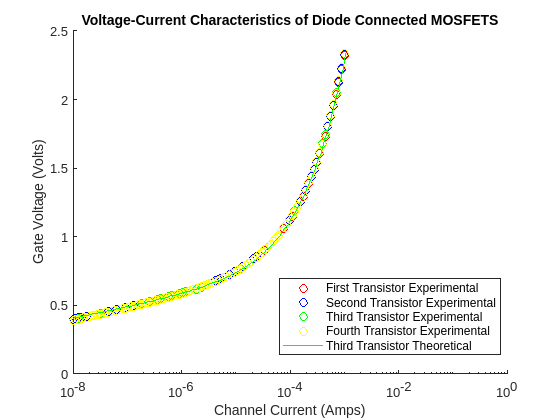

Ut = 0.025;
load("exp1_1_new.mat")

voltage1 = Diode_Voltage;
current1 = ch1;
[Is1, VT1, k1] = ekvfit(voltage1, current1, 0.0005);

load("exp1_2_new.mat")

voltage2 = Diode_Voltage;
current2 = ch1;
[Is2, VT2, k2] = ekvfit(voltage2, current2, 0.0005);

load("exp1_3_new.mat")

voltage3 = Diode_Voltage;
current3 = ch1;
[Is3, VT3, k3] = ekvfit(voltage3, current3, 0.0005);
load("exp1_4_new.mat")

voltage4 = Diode_Voltage;
current4 = ch1;
[Is4, VT4, k4] = ekvfit(voltage4, current4, 0.0005);
clf
figure(1)

[Is, VT, k] = ekvfit(voltage3, current3, 0.0005);
compute_current = @(voltage) Is .* log(1 + exp((k*(voltage-VT))/(2*Ut))).^2;
theoretical_current1 = compute_current(voltage3);

hold on 
title("Voltage-Current Characteristics of Diode Connected MOSFETS")
ylabel("Gate Voltage (Volts)")
xlabel("Channel Current (Amps)")
plot(current1,voltage1, 'ro','DisplayName',"First Transistor Experimental")
plot(current2,voltage2, 'bo','DisplayName',"Second Transistor Experimental")
plot(current3,voltage3, 'go','DisplayName',"Third Transistor Experimental")
plot(current4,voltage4, 'yo','DisplayName',"Fourth Transistor Experimental")
plot(theoretical_current1, voltage3, 'g-', 'DisplayName',"Third Transistor Theoretical")
set(gca, "XScale", "log");
xlim([10^-8, 1])
legend('show', 'Location', 'best');
hold off

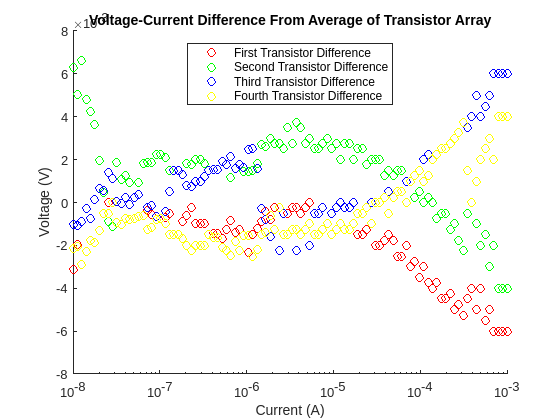

mean = (flip(voltage1) + flip(voltage2) + flip(voltage3) + flip(voltage4))/4;

clf;
figure(2)
hold on
title("Voltage-Current Difference From Average of Transistor Array")
ylabel("Voltage (V)")
xlabel("Current (A)")
plot(flip(current1), flip(voltage1) - mean, 'ro','DisplayName',"First Transistor Difference")
plot(flip(current2), flip(voltage2) - mean, 'go','DisplayName',"Second Transistor Difference")
plot(flip(current3), flip(voltage3) - mean, 'bo', 'DisplayName',"Third Transistor Difference")
plot(flip(current4), flip(voltage4) - mean, 'yo','DisplayName',"Fourth Transistor Difference")
set(gca, "XScale", "log");
legend('show', 'Location', 'best');
hold off

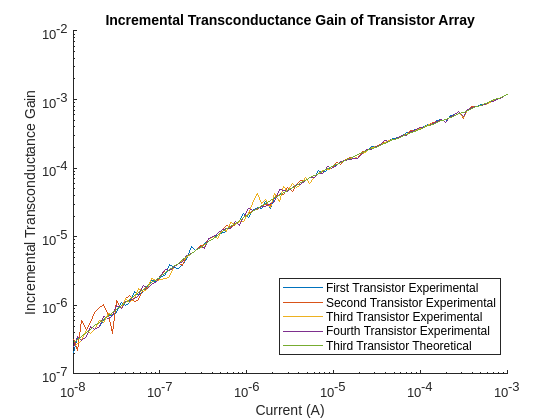


compute_gm = @(current, Is, k) k.*(sqrt(Is .* current)./Ut) .* (1-exp(-sqrt(current./Is)));

exp1_gm = diff(current1)./diff(voltage1);
exp2_gm = diff(current2)./diff(voltage2);
exp3_gm = diff(current3)./diff(voltage3);
exp4_gm = diff(current4)./diff(voltage4);

theo3_gm = compute_gm(current3, Is , k);
clf;
figure(7);
hold on
title("Incremental Transconductance Gain of Transistor Array")
ylabel("Incremental Transconductance Gain")
xlabel("Current (A)")
plot(current1(2:end), exp1_gm, 'DisplayName',"First Transistor Experimental")
plot(current2(2:end), exp2_gm, 'DisplayName',"Second Transistor Experimental")
plot(current3(2:end), exp3_gm, 'DisplayName',"Third Transistor Experimental")
plot(current4(2:end), exp4_gm, 'DisplayName',"Fourth Transistor Experimental")
plot(current3, theo3_gm, 'DisplayName',"Third Transistor Theoretical");
legend('show', 'Location', 'best');
set(gca, "XScale", "log");
set(gca, "YScale", "log");
hold off

## Experiment 2

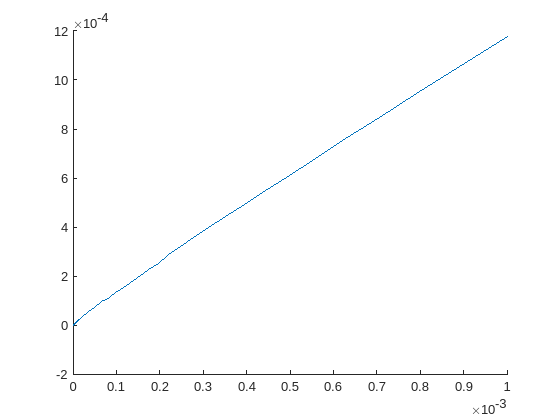

clear;
clf;
load("Ex_2_1.mat");
figure(3);
hold on
loglog(ch1, MDiode_Current);
hold off

## Experiment 3

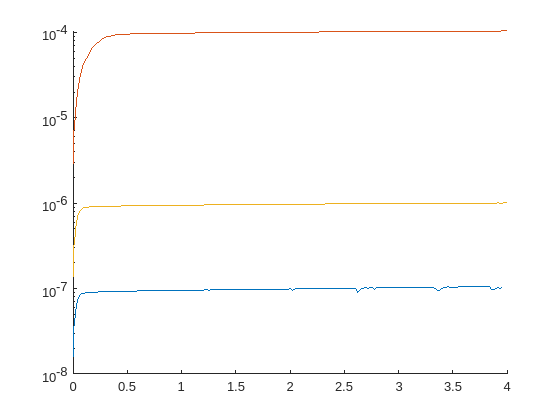

clear;
clf;
load("Ex_3_100nano.mat");
nano_100_voltage = ch2_voltage;
nano_100_current = mos_current;
load("Ex_3_1micro.mat");
micro_1_voltage = ch2_voltage;
micro_1_current = mos_current;
load("Ex_3_100micro.mat")
micro_100_voltage = ch2_voltage;
micro_100_current = mos_current;

figure();
hold on
plot(nano_100_voltage, nano_100_current);
plot(micro_100_voltage, micro_100_current);
plot(micro_1_voltage, micro_1_current);
set(gca, "YScale", "log");
xlim([0 4])
hold off